# PD制御による比例ゲインと系の応答

clear

g  = 9.81;                % 重力加速度[m/s^2]
l  = 0.2;                 % アームの長さ[m]
M  = 0.5;                 % アームの質量[kg]
mu = 1.5e-2;              % 粘性摩擦係数[kg*m^2/s]
J  = 1.0e-2;              % 慣性モーメント[kg*m^2]

P = tf( [0,1], [J, mu, M*g*l] );

ref = 30; % 目標角度 [deg]

kp = 2

kp = 2

kd = [0.3, 0.4, 0.5]

kd =     0.3000    0.4000    0.5000


param = 3

param = 3

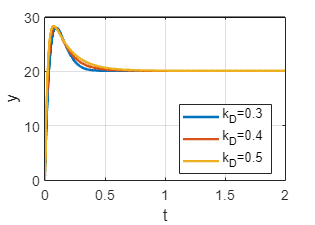

t = 0:0.01:2;
figure();
for i = 1:1:size(kd,2)
    K = tf([kd(i), kp], [0, 1]);
    Gyr = feedback(P*K, 1);
    y = step( Gyr, t);
    plot(t,y*ref, 'linewidth', 2, 'DisplayName','k_D='+string(kd(i)))
    hold on;
end
plot_set(gcf, 't', 'y', 'best')
plot(t, ref*ones(1,size(t,2)), 'k');

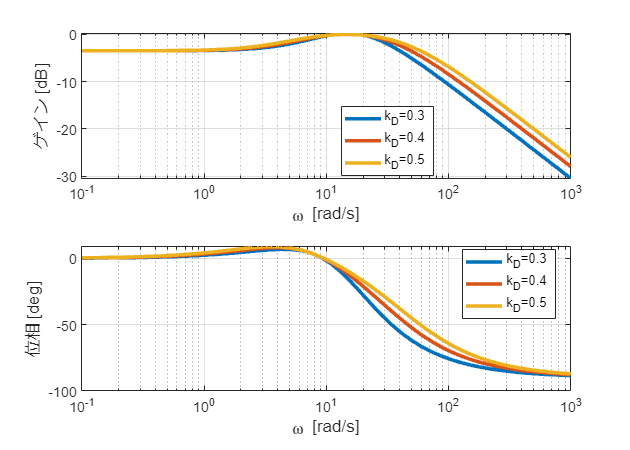

figure();
for i=1:1:size(kd,2)
    K = tf([kd(i), kp], [0, 1]);
    Gyr = feedback(P*K, 1);
    [gain, phase, w] = bode(Gyr, logspace(-1, param));
    
    gainLog = 20*log10(gain(:));
    phaseDeg = phase(:);
    
    subplot(2,1,1);
    semilogx(w, gainLog, 'LineWidth', param, 'DisplayName','k_D='+string(kd(i)));
    hold on;
    subplot(2,1,2);
    semilogx(w, phaseDeg, 'LineWidth', param, 'DisplayName','k_D='+string(kd(i)));
    hold on;

end
subplot(2,1,1); bodeplot_set(gcf, '\omega [rad/s]', 'ゲイン [dB]', 'best');
subplot(2,1,2); bodeplot_set(gcf, '\omega [rad/s]', '位相 [deg]', 'best');